# Engineering MATLAB: Week 14 Lecture

**2D Arrays**

clear, clc, close all;

## 2D Array Basics

A 2D array, more commonly known to us as matrcies, are data structures of the form


$$A = \left[ \matrix{ 1 & 2 \cr 3 & 4} \right]$$


In code, this is typed as

A = [1 2; 3 4]

A =      1     2
     3     4


### 2D Array Operations

For 2D arrays, we can follow all the rules of linear algebra for matrix operations. These include:

- Addition

A = rand(3,3)

A =     0.5853    0.2858    0.3804
    0.5497    0.7572    0.5678
    0.9172    0.7537    0.0759


B = rand(3,3)

B =     0.0540    0.9340    0.4694
    0.5308    0.1299    0.0119
    0.7792    0.5688    0.3371


A + B

ans =     0.6392    1.2198    0.8498
    1.0805    0.8871    0.5797
    1.6964    1.3226    0.4130


- Subtraction

A - B

ans =     0.5313   -0.6482   -0.0889
    0.0189    0.6273    0.5559
    0.1380    0.1849   -0.2613


- Multiplication (if the rows/columns meet the criteria)

A*B

ans =     0.4797    0.8002    0.4064
    0.8740    0.9348    0.4585
    0.5087    0.9977    0.4651


- Inverses (if invertible)

inv(A)

ans =     1.9868   -1.4212    0.6743
   -2.5688    1.6329    0.6605
    1.5021    0.9595   -1.5336


A \ B % this is A^(-1)B or inv(A)*B

ans =    -0.1218    2.0546    1.1430
    1.2428   -1.8115   -0.9637
   -0.6046    0.6553    0.1995


- Determinants

det(A)

ans = -0.1865

det(B)

ans = -0.0623

- Diagonals (diag command)

diag(A)

ans =     0.5853
    0.7572
    0.0759


- Trace (trace command)

trace(A)

ans = 1.4183

- eye(N) - NxN identity matrix

5*eye(3)

ans =      5     0     0
     0     5     0
     0     0     5


### 2D Array Indexing

You now have two dimensions to index and reference array values. Mathematically, we call a specific value inside the matrix $A$ as $A_{ij} = [a_{ij}]$. In code, this is written as

B = [1 2 3; 4 5 6; 7 8 9]

B =      1     2     3
     4     5     6
     7     8     9


B(1,1)

ans = 1

B(2,3)

ans = 6

We can also use the colon operator : to index a whole row or column as such:

first_row = B(1,:) % this reads as first row, every column

first_row =      1     2     3


second_col = B(:,2) % this reads as all rows, second column

second_col =      2
     5
     8


A = floor(50*rand(8,8))

A =      8    34    26    40     9    42     9    16
    39    37    49    43    13    31    11    45
    15    22     3     4     7    17    20    18
    26     4    22    19     6    25     2     5
     8    11     5    12    43    20    45    39
    30    45    48    40    28     3    47    19
    13     7     0    21    27    11    24    12
    32    41    38    45     7     6    24    20


A(5,7)

ans = 45

### Looping with 2D Arrays

When iterating through 2D arrays, we can use the colon operator when needed but also for loops

A 1D array requires a a single for loop, whereas a 2D array requires a for loop for the rows and another for loop for the columns

% lets create a matrix 
% preallocate a 3x3 matrix
C = zeros([3,3])

C =      0     0     0
     0     0     0
     0     0     0


for row = 1:3
    for col = 1:3
        C(row, col) = row * col^2;
    end
end

C

C =      1     4     9
     2     8    18
     3    12    27


% another way of creating matrices
row = 1:5; col = 1:4

col =      1     2     3     4


D(row, col) = 5

D =      5     5     5     5
     5     5     5     5
     5     5     5     5
     5     5     5     5
     5     5     5     5


## 2D Array Applications

### Linear Algebra, Systems of Equations

Now we can compute linear algebra problems. This is essentially solving systems of equations.

For example, lets solve the system


$$x + 2y + z - t = 5$$



$$\frac{3}{2}x + y + 2z + 2t = 8$$



$$4x +4y + 3z + 4t = 22$$



$$\frac{2}{5} x + \frac{1}{5}z + t = 3$$


We can represent this system as 


$$A \vec{x} = \vec{b}$$


with 

$A = \left[ \matrix{1 & 2 & 1 & -1 \cr 1.5 & 1 & 2 & 2 \cr 4 & 4 & 3 & 4 \cr \frac{2}{5} & 0 & \frac{1}{5} & 1}\right], \ \vec{x} = \left[ \matrix{x \cr y \cr z \cr t} \right], \ \vec{b} = \left[ \matrix{5 \cr 8 \cr 22 \cr 3} \right]$.

We can solve this equation by taking the inverse, i.e

$\vec{x} = A^{-1} \vec{b}$.

In code,

% We will do this in class

### Collating Data: Storing computed data

We can structure this 2D array as something we may see in excel: two columns of data.

Lets say we want to experiment and determine the angle $\theta$ that produces the max range, so we iterate

for all $\theta \in [0, 90]$ by a step size of $\Delta \theta = 0.5^{\circ}$. Let $V_0 = 20$ m/s. The formula for the range is 


$$R = \frac{v_0^2 \sin(2\theta)}{g}$$


 We can do this as such:

v0 = 20; % 20 m/s
g = 9.81; % 9.81 m/s^2

% We will code this all in class

This says our max height of $40.7747$m is achieved when $\theta = 45^{\circ}$.

### Reading Data from Files and Storing in 2D Array

Lets practice reading some data. Now typically a 2D array isn't the best data structure for this process, but in a pinch it works well. The main data structure to use here is a Table, but we will cover that next week along with structures and cell arrays. 

For now, we will be working on the Housing datafile.

Here is a layout for each of the columns:

- CRIM per capita crime rate by town 

- ZN proportion of residential land zoned for lots over 25,000 sq.ft. 

- INDUS proportion of non-retail business acres per town 

- CHAS Charles River dummy variable (= 1 if tract bounds river; 0 otherwise) 

- NOX nitric oxides concentration (parts per 10 million) 

- RM average number of rooms per dwelling 

- AGE proportion of owner-occupied units built prior to 1940 

- DIS weighted distances to five Boston employment centres 

- RAD index of accessibility to radial highways 

- TAX full-value property-tax rate per $10,000 

- PTRATIO pupil-teacher ratio by town 

- B 1000(Bk - 0.63)^2 where Bk is the proportion of blacks by town 

- LSTAT % lower status of the population 

- MEDV Median value of owner-occupied homes in $1000's

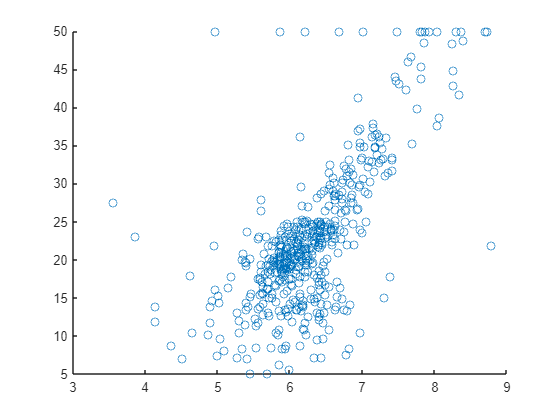

M = readmatrix("housing.csv");

crime = M(:,1);
zone  = M(:,2);
indus = M(:,3);
chas  = M(:,4);
nox   = M(:,5);
rm    = M(:,6);
age   = M(:,7);
dis   = M(:,8);
rad   = M(:,9);
tax   = M(:,10);
ptratio = M(:, 11);
b_perc  = M(:,12);
lstat   = M(:,13);
medv    = M(:, 14);

% lets investigate this data with some scatter plots
figure()
scatter(rm, medv)

% lets make a regression line (In Class)

## Problems

### Problem 1

Lets improve on the regression line above. What we have here is the equation


$$Y = X \beta_1$$


where $Y$ and $X$ are matrices and $\beta_1$ is a column vector. The way we can enhance this equation is by making a line:


$$y_i = \beta_1 x_i + \beta_2$$


This will be done by making $X$ a matrix with the first column of only ones. You can achieve this by writing

% X_new = [ones(length(X), 1), X]

Now repeat the process above and plot the new regression line

% Enter your code here

### Problem 2

Make a function to calculate the $R^2$ value given by the formula:


$$R^2 = 1 - \frac{\sum\limits_{i = 1}^{N} (y_i - \hat{y}_i)^2}{\sum\limits_{i=1}^{N} (y_i - \bar{y})^2}$$


where $\hat{y}_i$ represents the value in yCalc1 or yCalc2 (Problem 1 should have a yCalc2) and $\bar{y}$ is the mean of the vector $y$.

% rsq1 = CalculateRSq(Y, yCalc1)

% compute rsq2:

### Problem 3

Investigate the housing dataset and try to find any other variables with interesting connections. Be sure to plot your regression lines and write a small summary about your prediction.

%%%%%%%%%%%%%%%%%%
% Functions Here %
%%%%%%%%%%%%%%%%%%


function rsq = CalculateRSq(y, ycalc)

num = sum((y - ycalc).^2);
denom = sum((y - mean(y)).^2);

rsq = 1 - (num/denom);

end
